# Exam 2017

## Problem 1: Decompose a Linear Phase Filter

Linear phase filters with the symmetry property are commonly applied in audio signal processing due to their frequency independent group delay.

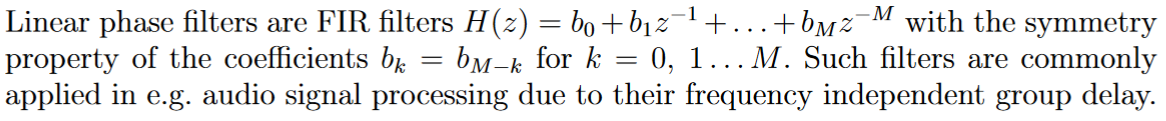

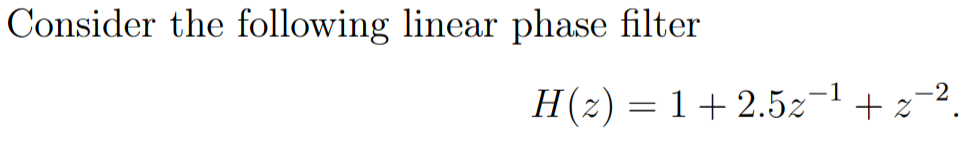

h = [1, 2.5, 1];

### 1) Rewrite the system function as a product of a minimum phase filter and an all-pass filter

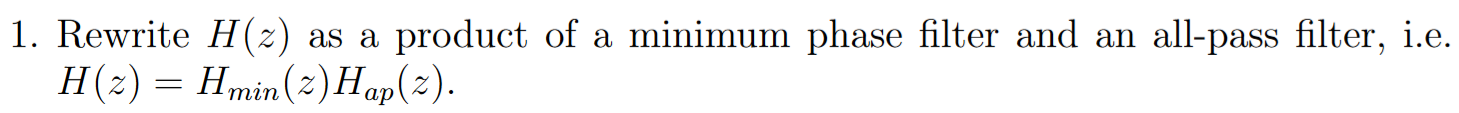

Any system function can be decomposed into a product of a minimum-phase filter and an all-pass filter using the following formula:

    
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$
  

The minimum phase filter can be computed as follows:

    
$$H_{\min } \left(z\right)=\prod_i \;-\frac{1}{{a_i }^* }H_i \left(z\right)\left(1-a_i z^{-1} \right)$$


where $H_i \left(z\right)$ corresponds to the part of the transfer function where the i'th zero is inside the unit circle and $z_i$ is the zero outside the unit circle. To get the zero $z_i$ inside the unit circle, we use the trick $a=\frac{1}{z_0 }$.

The allpass filter can be calculated:


$$H_{\textrm{ap}} \left(z\right)=\prod_i \frac{z^{-1} -{a_i }^* }{1-a_i z^{-1} }\;$$


The filter decomposition algorithm has following steps:

- Convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

- Compute $a$ and its conjugate $a^*$

- Compute $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

- Plugin the numbers for the formula for the minimum-phase filter

- Plugin the numbers for the formula for the allpass filter 

- Put everything together

These steps are coded in MATLAB function (see at the end of the document):

[H_min, H_ap] = decompose_min_ap(h)

$$H\_min = \frac{2}{z}+\frac{1}{2\,z^{2}}+2$$

$$H\_ap = \frac{\frac{1}{z}+\frac{1}{2}}{\frac{1}{2\,z}+1}$$

So we have:

        $H_{\mathrm{min}} \left(z\right)=2+2z^{-1} +\frac{1}{2}z^{-2}$  and  $H_{\mathrm{ap}} \left(z\right)=\frac{0\ldotp 5+z^{-1} }{1+0\ldotp 5z^{-1} }$

### 2) Discuss what happens to a signal if it is filtered using only $H_{\mathrm{min}} \left(z\right)$ instead of $H\left(z\right)$?

The two system functions $H\left(z\right)$ and $H_{\mathrm{min}} \left(z\right)$ have the same magnitude response, but their phase properties differ. In this particular case the $H\left(z\right)$ is a linear phase filter and the group delay through the filter is constant and independent of frequency. For the minimum phase system function the phase is not linear and the group delay becomes frequency dependent. A signal passing through $H_{\mathrm{min}} \left(z\right)$ instead of $H\left(z\right)$ will thus become phase distorted.

## Problem 2: Lattice Structures

Many different lattice structure have been investigated over the years, often tailored to specific requirements. One particular example is based on minimizing hardware requirements and uses only one multiplication per stage. The structure of the *m*’th stage of a one-multiplier lattice filter is shown below. The input and output is connected as for standard all-pole filters.

        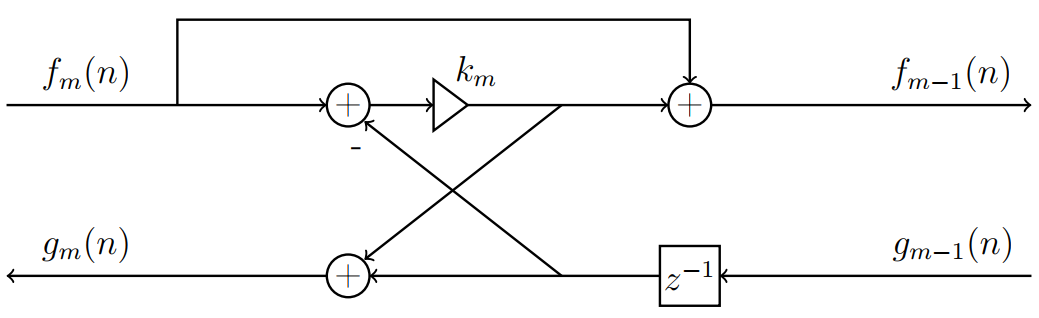

clear variables;

### 1) Determine the two equations relating outputs to inputs

        
$$f_{m-1} \left(n\right)=f_m \left(n\right)+k_m \left(f_m \left(n\right)-g_{m-1} \left(n\right)\right)$$


                    
$$=f_m \left(n\right)+k_m f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


                    
$$=\left(1+k_m \right)f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


        
$$g_m \left(n\right)=g_{m-1} \left(n-1\right)+k_m \left(f_m \left(n\right)-g_{m-1} \left(n\right)\right)$$


                  
$$=g_{m-1} \left(n-1\right)+k_m f_m \left(n\right)-k_m g_{m-1} \left(n\right)$$


                  
$$=k_m f_m \left(n\right)+\left(1-k_m \right)g_{m-1} \left(n-1\right)$$


### 2) When is the first non-zero sample observed at the output?

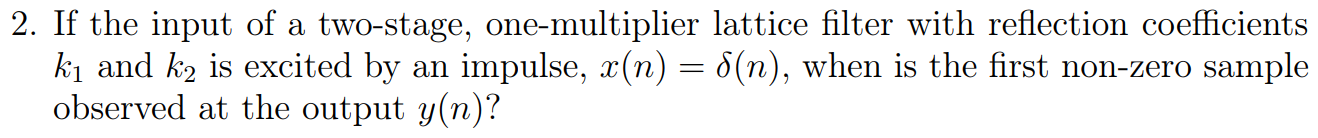

The two-stage, one multiplier lattice looks like this:

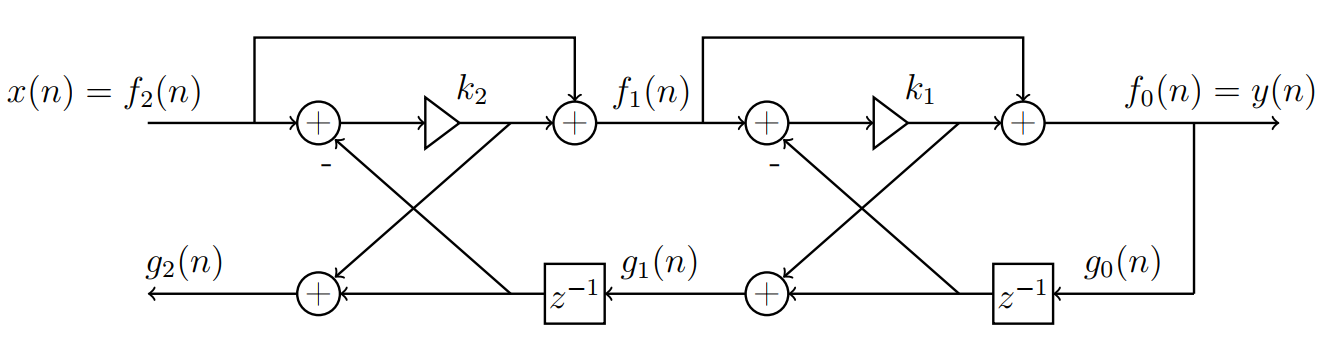

We found that the equation relating output to input is:

        
$$f_{m-1} \left(n\right)=\left(1+k_m \right)f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


Since we want the first output, we do not concern ourselves with the $g_{m-1} \left(n-1\right)$.

First, we compute $f_1 \left(n\right)$:

        
$$f_1 \left(n\right)=\left(1+k_2 \right)f_2 \left(n\right)=\left(1+k_2 \right)x\left(n\right)$$


Next, we compute $f_0 \left(n\right)$:

        
$$f_0 \left(n\right)=\left(1+k_1 \right)f_1 \left(n\right)=\left(1+k_1 \right)\left(1+k_2 \right)x\left(n\right)=y\left(n\right)$$


Since there is a direct path without any delays from input $x\left(n\right)$ to the output $y\left(n\right)$, the first non-zero sample appears instantaneously at the output. 

        
$$y\left(n\right)=\left(1+k_1 \right)\left(1+k_2 \right)x\left(n\right)$$


### 3) Calculate the transfer function for a one-stage lattice filter

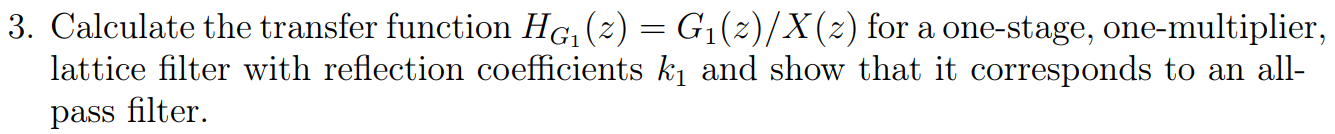

The one-stage, one multiplier lattice looks like this.  

        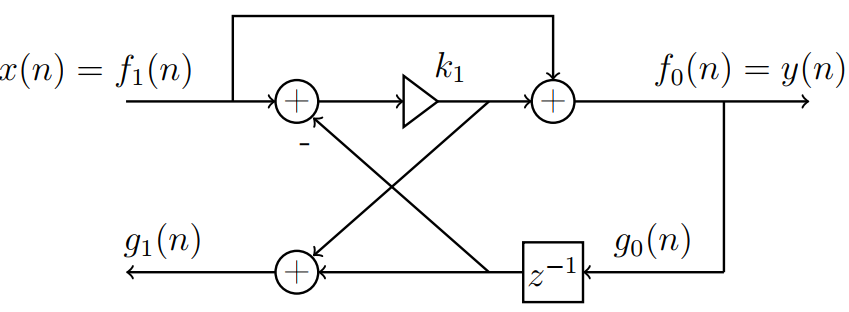

The equations relating the inputs and outputs are:

        
$$f_0 \left(n\right)=\left(1+k_1 \right)f_1 \left(n\right)-k_1 g_0 \left(n-1\right)$$


        
$$g_1 \left(n\right)=k_1 f_1 \left(n\right)+\left(1-k_1 \right)g_0 \left(n-1\right)$$


To calculate transfer functions, the two equations are first *z*-transformed:

        $F_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)-k_1 z^{-1} G_0 \left(z\right)$  Eq. (1)

        $G_1 \left(z\right)=k_1 F_1 \left(z\right)+\left(1-k_1 \right)z^{-1} G_0 \left(z\right)$  Eq. (2)

We know that $F_1 \left(z\right)=X\left(z\right)$ and $F_0 \left(z\right)=G_0 \left(z\right)=Y\left(z\right)$. 

We use the identity $F_0 \left(z\right)=G_0 \left(z\right)$ to rewrite our Eq. (1):

        
$$G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)-k_1 z^{-1} G_0 \left(z\right)$$


        
$$G_0 \left(z\right)+k_1 z^{-1} G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)$$


        
$$\left(1+k_1 z^{-1} \right)G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)$$


        
$$G_0 \left(z\right)=\frac{\left(1+k_1 \right)F_1 \left(z\right)}{1+k_1 z^{-1} }$$


Substitutde the new expression into Eq. (2)

        
$$G_1 \left(z\right)=k_1 F_1 \left(z\right)+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }F_1 \left(z\right)$$


We know that $F_1 \left(z\right)=X\left(z\right)$:

        
$$G_1 \left(z\right)=k_1 X\left(z\right)+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }X\left(z\right)$$


        
$$G_1 \left(z\right)=X\left(z\right)\left(k_1 +\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }\right)$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=k_1 +\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 \left(1+k_1 z^{-1} \right)}{1+k_1 z^{-1} }+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 \left(1+k_1 z^{-1} \right)+\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


syms k z
expand(k*(1+k*z)+(1-k)*(1+k)*z)

$$ans = k+z$$

        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 +z^{-1} }{1+k_1 z^{-1} }$$


An allpass filter has the form:

        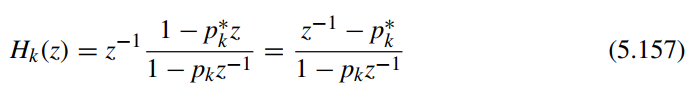

Higher order allpass systems can be obtained by cascading multiple first-order sections, as  

        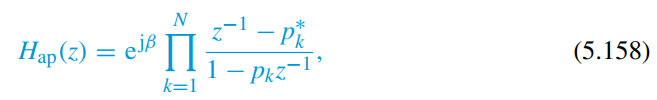

## Problem 3: Detect presence of signal using matched filter

Consider the deterministic signal, *s*(*n*) shown below in blue. The signal is zero for all other values of  *n*.  

        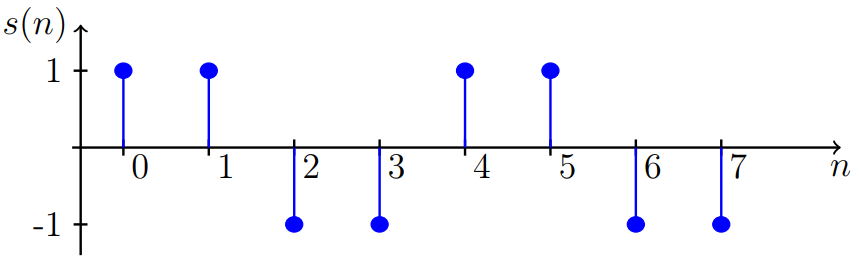

The signal is distorted by additive low frequency noise with autocorrelation $r_v \left(\ell \right)=0\ldotp 4^{|\ell |}$.

### 1) Design a matched filter for detecting the presence of the signal and determine the improvement in signal to noise ratio.  

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        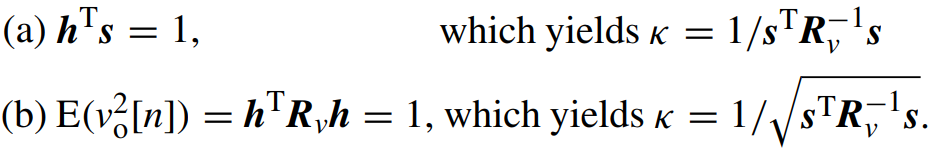

s = [1, 1, -1, -1, 1, 1, -1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/(s'*(R_vv\s));     % Using (a)
k = 1/sqrt(s'*(R_vv\s)); % Using (b)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

% Print the matched filter coefficients
h

h =     0.2292
    0.4431
   -0.4431
   -0.4431
    0.4431
    0.4431
   -0.4431
   -0.2292


The optimum SNR at the output is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 9.7143

  The SNR at the input is given by:

        
$${\mathrm{SNR}}_i =\frac{{\left(\mathrm{Value}\;\mathrm{of}\;\mathrm{signal}\;\mathrm{at}\;n=n_0 \right)}^2 }{\mathrm{power}\;\mathrm{of}\;\mathrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

SNR_i = 1

The improvement in SNR is 9.7 (almost 10 times)

### 2) Discuss the improvement of SNR if another signal is used

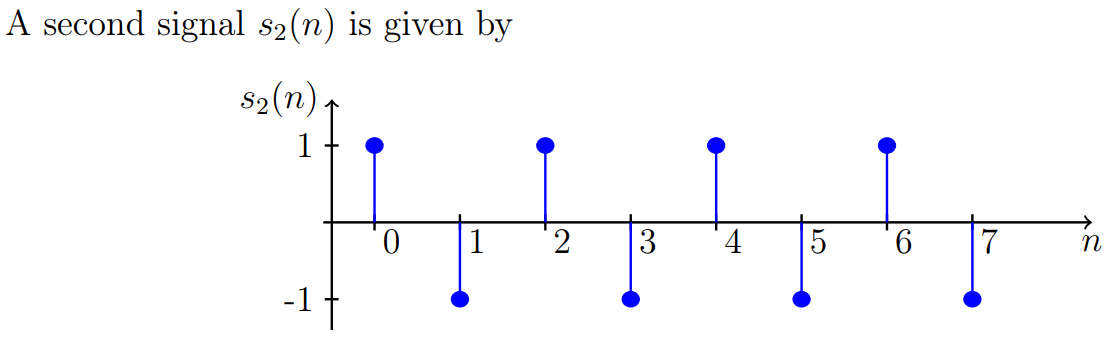

If we use $s_2 \left(n\right)$ instead of $s\left(n\right)$, the output SNR becomes 17.3:

s = [1, -1, 1, -1, 1, -1, 1, -1]';
p = numel(s); % Signal length
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);
a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 17.3333

The $s_2 \left(n\right)$ is similar to $s\left(n\right)$ but it oscillates faster i.e., has higher frequency than the $s\left(n\right)$ signal. Since the noise is at low frequency, it is easier to separate the $s_2 \left(n\right)$ signal from the noise. This means that a higher SNR can be expected from a signal with a higher frequency.

That is why the output SNR for $s_2 \left(n\right)$ is better than that for $s\left(n\right)$.

## Problem 4: Recover signal using a Wiener filter

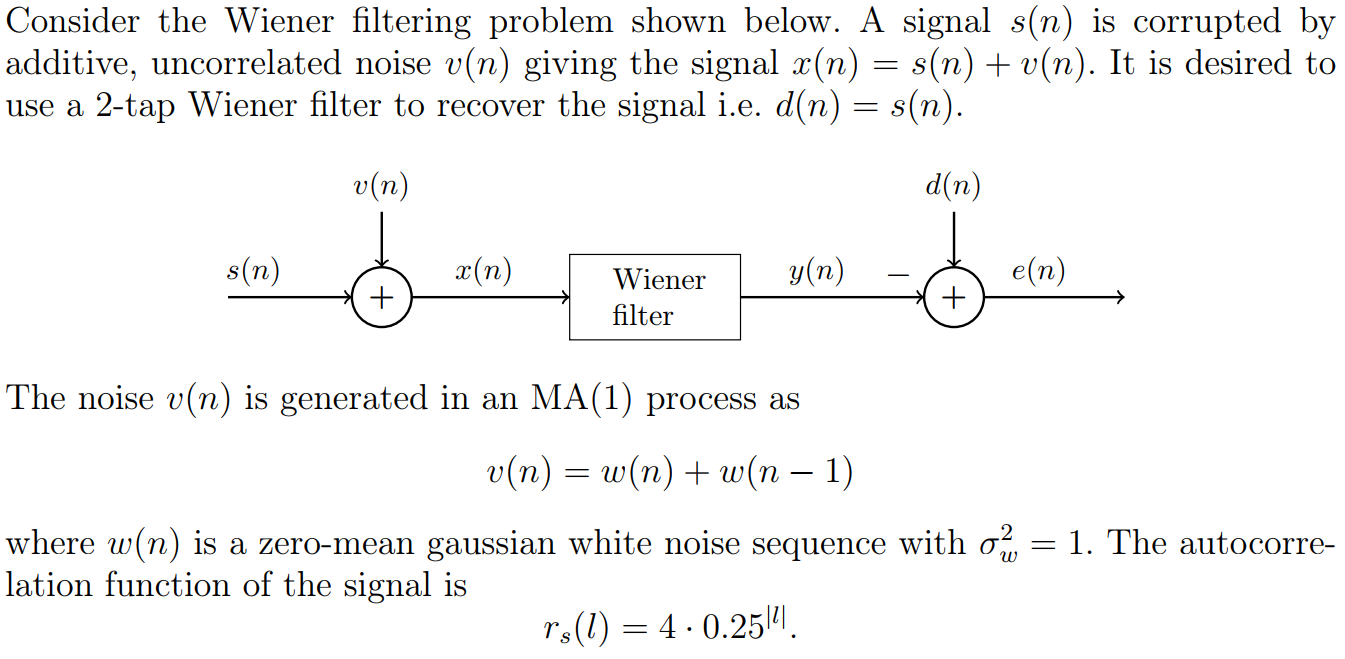

clear variables;

M = 2;
ell = 0:M-1;
delta = @(l) ell == l;

r_ss = 4*(0.25).^(abs(ell));

### 1) Compute the autocorrelation function of the noise

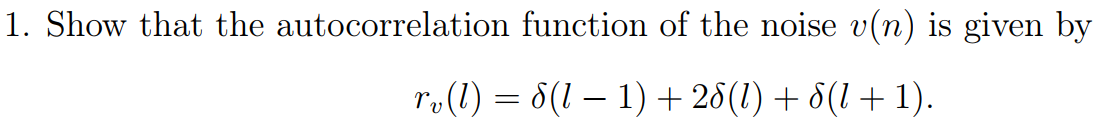

In ADSI Problem 4.9, we found that the autocorrelation for an MA(1) process where the input signal is a white noise with unit variance can be described as:

        
$$r_v \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


In this problem $b_0 =b_1 =1$:

        
$$r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$$


r_vv = delta(-1) + 2*delta(0) + delta(1)

r_vv =      2     1


### 2) Compute the optimum filter coefficients

The $p$-order Wiener filter for estimating the signal $s\left(n\right)$ is given by:

        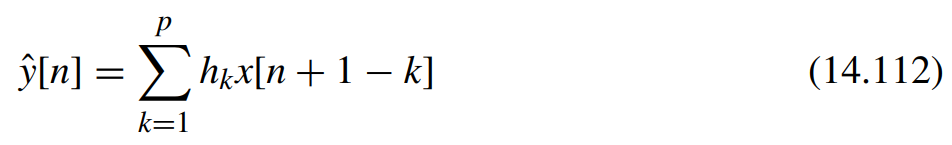

The optimum Wiener filter coefficients is given by the Wiener-Hopf equation:

        

where ${\mathit{\mathbf{R}}}_x$ is the autocorrelation matrix of the corrupted signal $s\left(n\right)$ and $\mathit{\mathbf{g}}$ is the cross-correlation between the desired signal $s\left(n\right)$ and the corrupted signal $x\left(n\right)$.

Designing a Wiener filter to recover a corrupted signal involves 3 steps:

- Compute the autocorrelation sequence $r_x \left(\ell \right)$ and matrix $R_x$

- Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$

- Solve the Wiener-Hopf equation to find the optimum Wiener filter coefficients

**Step 1:** Compute the autocorrelation $r_x \left(\ell \right)$:

Since the signal $s\left(n\right)$ and the noise $w\left(n\right)$ are uncorrelated the autocorrelation function of $s\left(n\right)$ is just the sum of the individual autocorrelation functions:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)v\left(n-\ell \right)+v\left(n\right)s\left(n-\ell \right)+v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)+r_v \left(\ell \right)$$


Since $s\left(n\right)$ and $v\left(n\right)$ are uncorrelated $r_{\mathrm{sv}} \left(\ell \right)=0$. We computed $r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$: 

        
$$r_x \left(\ell \right)=r_s \left(\ell \right)+r_v \left(\ell \right)$$


r_xx = r_ss + r_vv;
R_xx = toeplitz(r_xx)

R_xx =      6     2
     2     6


**Step 2:** Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$:

Since the desired signal is $s\left(n\right)$, the cross-correlation between $s\left(n\right)$ and $s\left(n\right)$ simplifies to the autocorrelation of the signal $r_s \left(\ell \right)$.

        
$$r_{\textrm{yx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                  
$$=r_s \left(\ell \right)+r_{\mathrm{sv}} \left(\ell \right)$$


                  $=r_s \left(\ell \right)+0$   (since $s\left(n\right)$ and $v\left(n\right)$ are uncorrelated $r_{\textrm{sv}} \left(\ell \right)=0$

g = r_ss'

g =      4
     1


**Step 3:** Compute the optimum filter coefficients:

h_opt = R_xx\g

h_opt =     0.6875
   -0.0625


### 3) Calculate SNR before and after the Wiener filter

The signal to noise ratio of the input signal is given by

        
$${\textrm{SNR}}_i =\frac{{\left(\textrm{value}\;\textrm{of}\;\textrm{signal}\;\textrm{at}\;n=n_0 \right)}^2 }{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}=\frac{r_s \left(0\right)}{r_v \left(0\right)}$$


We know that:

        $r_s \left(\ell \right)=4\cdot 0\ldotp {25}^{|\ell |}$  and   $r_v \left(\ell \right)=\delta \left(\ell -1\right)+2\delta \left(\ell \right)+\delta \left(\ell +1\right)$

This means:

        $r_s \left(0\right)=4$  and  $r_v \left(0\right)=2$

Thus:

        
$${\textrm{SNR}}_i =\frac{r_s \left(0\right)}{r_v \left(0\right)}=\frac{4}{2}=2$$


The output SNR of the Wiener filter is given by:

        
$${\mathrm{SNR}}_o =\frac{h_{\mathrm{opt}}^T R_s h_{\mathrm{opt}} }{h_{\mathrm{opt}}^T R_v h_{\mathrm{opt}} }$$


R_ss = toeplitz(r_ss);
R_vv = toeplitz(r_vv);
SNR_o = (h_opt'*R_ss*h_opt) / (h_opt'*R_vv*h_opt)

SNR_o = 2.0991

The filter increases the SNR but only slightly. This is expected and is an excellent way to check your results.

# Functions

function [h]=filter_coeff(rational_system_expr, z)
    h = coeffs(expand(rational_system_expr * z^10), 'all');
    h = h(1:find(h, 1, 'last'));
end

function [H_min, H_ap]=decompose_min_ap(h)
    % Decomposes a filter into minimum-phase filter and all-pass filter
    %  h: the filter coefficients
    syms z;
    rts = roots(h);
    
    H_outside = 1; % Represents part of H where zeros are outside the unit circle
    H_inside = 1;  % Represents part of H where zeros are inside the unit circle
    zeros_outside = [];
    for i = 1:numel(rts)
        root = rts(i);
        if abs(root) > 1
            H_outside = H_outside * (1 - root*z^-1);
            zeros_outside = [zeros_outside; root];
        else
            H_inside = H_inside * (1 - root*z^-1);
        end
    end

    % Sanity check
    % H = expand(H_inside * H_outside)
    
    % Compute minimum-phase filter and all-pass filter
    H_min = 1;
    N = numel(zeros_outside);
    H_ap = 1;
    for i = 1:N
        z_i = zeros_outside(i);
        a = 1/z_i;
        a_conj = conj(a);
        H_min = H_min * (-(1/a_conj) * H_inside * (1-a * z^(-1)));
        H_ap = H_ap * (z^(-1) - a_conj) / (1 - a*z^(-1));
    end
    H_min = expand(H_min);
end